### 文件输入区


% 171和173分开装载，分别进动 %

close all
clear all
colors=npg(10); % Ten basic colors
tpi = 2*pi;
gamma171 = 7.50e6;   % freq, Hz/T
gamma173 = 2.07e6*5;



% 171 near %
maindir='\\Artemis-pc\Data\2026-08-07\Abs-688\';   % 靠近，对比度
%load([maindir,'\FitResult.mat']);
load([maindir,'\repeat_amp.mat']);
%load([maindir,'\repeat_amp_Tknow.mat']);
a171n = amp(1);   % 171 对比度
a171n_sigma = a_sigma(1);

% 171 far %
maindir='\\Artemis-pc\Data\2026-08-07\Abs-773\';   % 远离，对比度
%load([maindir,'\FitResult.mat']);
load([maindir,'\repeat_amp.mat']);
%load([maindir,'\repeat_amp_Tknow.mat']);
a171f = amp(1);   % 171 对比度
a171f_sigma = a_sigma(1);

% 173 near %
maindir='\\Artemis-pc\Data\2026-08-07\Abs-731\';   % 靠近，对比度
%load([maindir,'\FitResult.mat']);
load([maindir,'\repeat_amp.mat']);
%load([maindir,'\repeat_amp_Tknow.mat']);
a173n = amp(1);   % 173 对比度
a173n_sigma = a_sigma(1);

% 173 far %
maindir='\\Artemis-pc\Data\2026-08-07\Abs-752\';   % 远离，对比度
%load([maindir,'\FitResult.mat']);
load([maindir,'\repeat_amp.mat']);
%load([maindir,'\repeat_amp_Tknow.mat']);
a173f = amp(1)-0.05;   % 173 对比度
a173f_sigma = a_sigma(1);



% maindir='\\Artemis-pc\Data\2026-08-03\';   % 远离，对比度
% load([maindir,'\amp.mat'], ...
%     'am171n','am171f','am173n','am173f', ...
%     'asm171n','asm171f','asm173n','asm173f');


### 数据输入区


save_data = 1;

maindir='\\Artemis-pc\Data\2026-08-07\Abs-342\';   % 相位数据
main_dir_0=maindir;
load([maindir,'\population.mat'],'s1','s2');
sz = (s1-s2)./(s1+s2);
sz([257:288]) = [];
sz([1:120]) = [];

if_delete = 0;
if if_delete == 1
    delete_sz_num = [100:106 141:142];
    delete_R_num = [35 27 26 25];
end

% ！！注意修改 周期数 和 进动时间 ！！ %

%inner_run = 'Y';   % 内层先循环元素，再循环转动距离，即[near171 near173 far171 far173]
inner_run = 'R';   % 先循环距离，再循环元素，即[171near 171far 173near 173far]

ts = 10;   % s,不包含旋转位移台时间
ROT_T = 4020;   % ms,转台2次转动总时间

ms171f = 20.5;   % ms,171,far
dms_Yb = 0.8;   % 173相对171
dms_nf = 1.5;   % ms,近 相对 远，171和173必须一致
ms171n = ms171f+dms_nf;   % ms,171,near

ms173f = ms171f+dms_Yb;   % ms,173,far
ms173n = ms173f+dms_nf;

N171 = 1258.75;%-300;
N173 = 1733.75;%-500;

coefficient171 = 2-4*(N171-floor(N171));   % 上坡+1,下坡-1
coefficient173 = 2-4*(N173-floor(N173));   % 上坡+1,下坡-1

wait1 = 4;   % ms
wait2 = 46;   % ms

%Yb_list = [171 173 173 171];   % 元素序列
Yb_list = [171 173];   % 元素序列
ROT_list = [1 -1 -1 1];   % 旋转序列，靠近(+1)，远离(-1)



Yb_len = length(Yb_list);
ROT_len = length(ROT_list);
nlist = Yb_len*ROT_len;
nData = length(sz);
loop_len = floor(nData/nlist);



for k = 1:ROT_len
    if ROT_list(k) == +1   % 靠近
        a171(k) = a171n;
        as171(k) = a171n_sigma;
        ms171(k) = ms171n;
        a173(k) = a173n;
        as173(k) = a173n_sigma;
        ms173(k) = ms173n;
    elseif ROT_list(k) == -1   % 远离
        a171(k) = a171f;
        as171(k) = a171f_sigma;
        ms171(k) = ms171f;
        a173(k) = a173f;
        as173(k) = a173f_sigma;
        ms173(k) = ms173f;
    end
end
% 进动时间，秒数在第一段修改 %
precession171 = ts*1e3 + ms171;   % 时序可设置的进动时间
tau171 = ts*1e3 + ROT_T + ms171 + wait1*2 + wait2;   % 包括转台转动时间，前后各2s
precession173 = ts*1e3 + ms173;   % 时序可设置的进动时间
tau173 = ts*1e3 + ROT_T + ms173 + wait1*2 + wait2;   % 包括转台转动时间，前后各2s



% if inner_run == 'Y'
%     for k = 1:Yb_len
%         if Yb_list(k) == 171
%             an(k) = a171n;
%             asn(k) = a171n_sigma;
%             msn(k) = ms171n;
%             af(k) = a171f;
%             asf(k) = a171f_sigma;
%             msf(k) = ms171f;
%         elseif Yb_list(k) == 173
%             an(k) = a173n;
%             asn(k) = a173n_sigma;
%             msn(k) = ms173n;
%             af(k) = a173f;
%             asf(k) = a173f_sigma;
%             msf(k) = ms173f;
%         end
%     end
%     % 进动时间，秒数在第一段修改 %
%     prece_n = ts*1e3 + msn;   % 时序可设置的进动时间
%     prece_total_n = ts*1e3 + ROT_T + msn;   % 包括转台转动时间，前后各2s
%     prece_f = ts*1e3 + msf;   % 时序可设置的进动时间
%     prece_total_f = ts*1e3 + ROT_T + msf;   % 包括转台转动时间，前后各2s
% 
%     taun = prece_total_n+0;
%     Nn = floor(taun./Tn);
%     tauf = prece_total_f+0;
%     %Nf = floor(tauf./Tf);
%     Nf = Nn;
% end


### 排除进动时间不同，主磁场累积的相位


for k = 1:ROT_len
    if ROT_list(k) == +1   % 靠近
        % 靠近对比远离有时间差，这段时间差内，主磁场积累的相位 %
        % 对应于剩磁在10s累积的相位 %
        p171mod(k) = ...
            tpi*N171*dms_nf/tau171(k);
        p173mod(k) = ...
            tpi*N173*dms_nf/tau173(k);
    elseif ROT_list(k) == -1   % 远离
        p171mod(k) = 0;
        p173mod(k) = 0;
    end
end


### 数据分组


count171 = 0;
count173 = 0;

for nloop = 1:loop_len

    % [171near 171far 173near 173far] %
    if inner_run == 'R'

        for nYb = 1:Yb_len
            kk = (nYb-1)*ROT_len+1:nYb*ROT_len;
            kk1 = (nloop-1)*nlist+kk;   % sz
            kk2 = count171*ROT_len+[1:ROT_len];
            kk3 = count173*ROT_len+[1:ROT_len];
            if Yb_list(nYb) == 171
                temp = sz(kk1)'./a171;
                dp171(kk2) = real(asin(temp));
                p171(kk2) = N171*tpi + coefficient171*dp171(kk2) - p171mod;
                f171(kk2) = p171(kk2)./(tau171*1e-3)/tpi;   % frequency Hz
                count171 = count171+1;
            elseif Yb_list(nYb) == 173
                temp = sz(kk1)'./a173;
                dp173(kk3) = real(asin(temp));
                p173(kk3) = N173*tpi + coefficient173*dp173(kk3) - p173mod;
                f173(kk3) = p173(kk3)./(tau173*1e-3)/tpi;   % frequency Hz
                count173 = count173+1;
            end
        end 
 
        % 待检查 %
        % [near171 near173 far171 far173] %
    elseif inner_run == 'Y'

        for nYb = 1:Yb_len
            kk = nYb:Yb_len:nlist;
            kk1 = (nloop-1)*nlist+kk;
            kk2 = count171*nlist/2+[1:ROT_len];
            kk3 = count173*nlist/2+[1:ROT_len];
            if Yb_list(nYb) == 171
                temp = sz(kk1)'./a171;
                dp171(kk2) = real(asin(temp));
                p171(kk2) = N171*tpi + coefficient171*dp171(kk2) - p171mod;
                f171(kk2) = p171(kk2)./(tau171*1e-3)/tpi;   % frequency Hz
                count171 = count171+1;
            elseif Yb_list(nYb) == 173
                temp = sz(kk1)'./a173;
                dp173(kk3) = real(asin(temp));
                p173(kk3) = N173*tpi + coefficient173*dp173(kk3) - p173mod;
                f173(kk3) = p173(kk3)./(tau173*1e-3)/tpi;   % frequency Hz
                count173 = count173+1;
            end
        end

    end

end


### 末端


end_num = loop_len*nlist+1;

if end_num < length(sz)
    sz_end = sz([end_num:end]);
    if inner_run == 'R'
        % 171和173成组 %
        n_loop_end = floor(length(sz_end)/(ROT_len*2));
        for k = 1:2*n_loop_end
            kk1 = (k-1)*ROT_len+1:k*ROT_len;
            %kk1 = (k-1)*ROT_len+kk;   % sz
            kk2 = count171*ROT_len+[1:ROT_len];
            kk3 = count173*ROT_len+[1:ROT_len];
            if Yb_list(k) == 171
                temp = sz_end(kk1)'./a171;
                dp171(kk2) = real(asin(temp));
                p171(kk2) = N171*tpi + coefficient171*dp171(kk2) - p171mod;
                f171(kk2) = p171(kk2)./(tau171*1e-3)/tpi;   % frequency Hz
                count171 = count171+1;
            elseif Yb_list(k) == 173
                temp = sz_end(kk1)'./a173;
                dp173(kk3) = real(asin(temp));
                p173(kk3) = N173*tpi + coefficient173*dp173(kk3) - p173mod;
                f173(kk3) = p173(kk3)./(tau173*1e-3)/tpi;   % frequency Hz
                count173 = count173+1;
            end
        end
    end
end

% k_mark = k;
% 
% end_num = (count171+count173)*ROT_len+1;
% 
% if end_num < length(sz)   
%     sz_end = sz([end_num:end]);
%     % 最后一组171&173,未完全成组 %
%     if inner_run == 'R'
%         n_loop_end = floor((length(sz_end)-ROT_len)/2);   % 171和173成组
%         sz_end = sz_end([1:2*n_loop_end,ROT_len+1:2*n_loop_end]);
%             if Yb_list(kmark+1) == 171
%                 temp = sz_end(kk1)'./a171;
%                 dp171(kk2) = real(asin(temp));
%                 p171(kk2) = N171*tpi + coefficient171*dp171(kk2) - p171mod;
%                 f171(kk2) = p171(kk2)./(tau171*1e-3)/tpi;   % frequency Hz
%                 count171 = count171+1;
%             elseif Yb_list(kmark+1) == 173
%                 temp = sz_end(kk1)'./a173;
%                 dp173(kk3) = real(asin(temp));
%                 p173(kk3) = N173*tpi + coefficient173*dp173(kk3) - p173mod;
%                 f173(kk3) = p173(kk3)./(tau173*1e-3)/tpi;   % frequency Hz
%                 count173 = count173+1;
%             end
%         end
%     end
% end



% 171总相位 %
mean(dp171)

ans = -0.0255

pm171 = mean(p171);
fm171 = mean(f171);

% 173总相位 %
mean(dp173)

ans = -0.0724

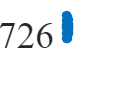

pm173 = mean(p173);
fm173 = mean(f173);

% 频率比 %
rf = f171./f173;
% 相位比 %
rp = p171./p173;
rpm=mean(rp);
rpstd=std(rp)/sqrt(length(rp)-1);
figure;
plot(1:length(rp),rp,'.','MarkerSize',12);
ylabel('phase ratio');
grid off;
box on;
set(gca,'FontSize',16,'FontName','Times New Roman');

### 差分相位


diff_n = floor(length(rp)/2);

for k = 1:diff_n/(ROT_len/2)
    
    kk = (k-1)*ROT_len+1:2:k*ROT_len-1;
    
    % 相位比 %
    temp1 = ROT_list(1:2:ROT_len-1).*rp(kk);
    temp2 = ROT_list(2:2:ROT_len).*rp(kk+1);
    diff_rp((kk+1)/2) = (temp1+temp2);
    % 频率比 %
    temp1 = ROT_list(1:2:ROT_len-1).*rf(kk);
    temp2 = ROT_list(2:2:ROT_len).*rf(kk+1);
    diff_rf((kk+1)/2) = (temp1+temp2);
    %temp = rf(kk);
    %diff_rf(k) = (ROT_list*temp')/(ROT_len/2);

    % 有效进动时间内,171累积的频率差 %
    temp1 = ROT_list(1:2:ROT_len-1).*p171(kk);
    temp2 = ROT_list(2:2:ROT_len).*p171(kk+1);
    df171((kk+1)/2) = (temp1+temp2) /(precession171(1)*1e-3) /tpi;   % Hz
    %temp = p171(kk)';
    %df171(k) = (ROT_list*temp)/(ROT_len/2) /(precession171(1)*1e-3) /tpi;   % Hz
    % 有效进动时间内,173累积的频率差 %
    temp1 = ROT_list(1:2:ROT_len-1).*p173(kk);
    temp2 = ROT_list(2:2:ROT_len).*p173(kk+1);
    df173((kk+1)/2) = (temp1+temp2) /(precession173(1)*1e-3) /tpi;   % Hz
    %temp = p173(kk)';
    %df173(k) = (ROT_list*temp)/(ROT_len/2) /(precession173(1)*1e-3) /tpi;   % Hz
end

if if_delete == 1
    diff_rp(delete_R_num) = [];
    df171(delete_R_num) = [];
    df173(delete_R_num) = [];
    diff_n = diff_n-length(delete_R_num);
end



dp = diff_rp*pm173;
dpm = mean(dp);
dps = std(dp)/sqrt(diff_n-1);
df = dp/mean(precession173)*1e6/tpi;   % frequency,mHz
dfm = mean(df);
dfs = std(df)/sqrt(diff_n-1);

dB171 = df171/gamma171*1e9;   % nT,有效进动时间内,171测得磁场差异
dBm171 = mean(dB171);
dBs171 = std(dB171)/sqrt(diff_n-1);

dB173 = df173/gamma173*1e9;   % nT,有效进动时间内,171测得磁场差异
dBm173 = mean(dB173);
dBs173 = std(dB173)/sqrt(diff_n-1);

% 差分频率比 %
drpm = mean(diff_rp);
drps = std(diff_rp)/sqrt(diff_n-1);
drfm = mean(diff_rf);
drfs = std(diff_rf)/sqrt(diff_n-1);


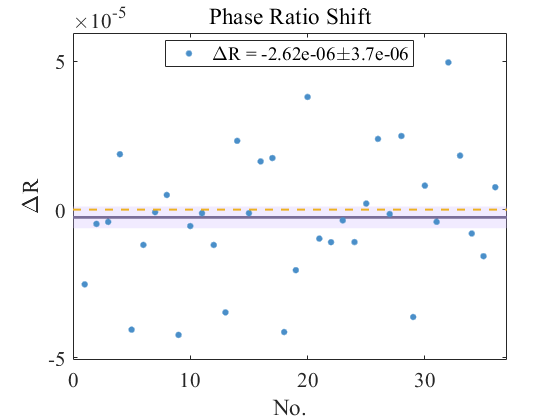


f1 = figure; hold on;

xmin = 0;
xmax = diff_n+1;
ymin = min([-abs(drpm*0.2) min(diff_rp)*0.8 min(diff_rp)*1.2]);
ymax = max([abs(drpm*0.2) max(diff_rp)*0.8 max(diff_rp)*1.2]);

n1 = [1 2 3 4];
patch_list = [0 drpm-drps ; diff_n+1 drpm-drps ; ...
    diff_n+1 drpm+drps ; 0 drpm+drps];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],'EdgeColor','none');
l1 = plot([0 xmax],[drpm drpm],Color=[0.48 0.43 0.60],LineWidth=2);

l2 = plot([1:diff_n],diff_rp,'.','MarkerSize',15);
l2.Color = [0.29,0.56,0.79];

l3 = plot([0 xmax],[0 0],'--','LineWidth',1.5,Color=[0.93 0.69 0.13]);

if diff_n < 6
    xticks([]);
end

xlim([xmin xmax]);
ylim([ymin ymax]);

xlabel('No.');
ylabel('\DeltaR');
title('Phase Ratio Shift');
legend('','',['\DeltaR = ',num2str(drpm,'%.2e'),'\pm',num2str(drps,'%.1e')],'',...
    'Location','best');
grid off;
box on;

set(f1,'Visible','on');
set(gca,'FontSize',16,'FontName','Times New Roman');

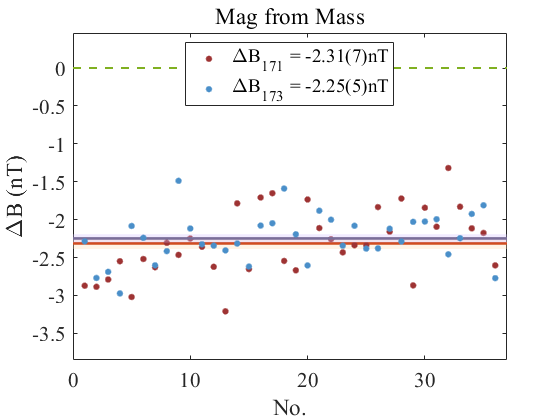


f11 = figure; hold on;
xmin = 0;
xmax = diff_n+1;
ymin = min([-abs([dBm171 dBm173]*0.2) min([dB171,dB173])*0.8 min([dB171,dB173])*1.2]);
ymax = max([abs([dBm171 dBm173]*0.2) max([dB171,dB173])*0.8 max([dB171,dB173])*1.2]);

% 171测得磁场差异 %
n1 = [1 2 3 4];
patch_list = [0 dBm171-dBs171 ; diff_n+1 dBm171-dBs171 ; ...
    diff_n+1 dBm171+dBs171 ; 0 dBm171+dBs171];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[1 0.85 0.67],'EdgeColor','none');
l11 = plot([0 xmax],[dBm171 dBm171],Color=[0.82 0.3 0.12],LineWidth=2);

l12 = plot([1:diff_n],dB171,'.','MarkerSize',15);
l12.Color = [0.62,0.2,0.2];


% 173测得磁场差异 %
n1 = [1 2 3 4];
patch_list = [0 dBm173-dBs173 ; diff_n+1 dBm173-dBs173 ; ...
    diff_n+1 dBm173+dBs173 ; 0 dBm173+dBs173];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],'EdgeColor','none');
l21 = plot([0 xmax],[dBm173 dBm173],Color=[0.48 0.43 0.60],LineWidth=2);

l22 = plot([1:diff_n],dB173,'.','MarkerSize',15);
l22.Color = [0.29,0.56,0.79];

l3 = plot([0 xmax],[0 0],'LineStyle','--','LineWidth',1.5,Color=[0.5 0.69 0.13]);


if diff_n < 6
    xticks([]);
end

xlim([xmin xmax]);
ylim([ymin ymax]);

xlabel('No.');
ylabel('\DeltaB (nT)');
title('Mag from Mass');
legend('','',['\DeltaB_{171} = ',num2str(dBm171,'%.2f'),'(',num2str(dBs171*1e2,'%.0f'),')nT'],...
    '','',['\DeltaB_{173} = ',num2str(dBm173,'%.2f'),'(',num2str(dBs173*1e2,'%.0f'),')nT'],'',...
    'Location','best');
grid off;
box on;

set(f11,'Visible','on');
set(gca,'FontSize',16,'FontName','Times New Roman');


% 171,173关联 %
% f12 = figure; hold on;
% xmin = min([min(dB171)*0.95 min(dB171)*1.05]);
% xmax = max([max(dB171)*0.95 max(dB171)*1.05]);
% ymin = min([min(dB173)*0.95 min(dB173)*1.05]);
% ymax = max([max(dB173)*0.95 max(dB173)*1.05]);
% 
% l1 = plot(dB171,dB173,'.','MarkerSize',15);
% l1.Color = [0.62,0.2,0.2];
% 
% xlim([xmin xmax]);
% ylim([ymin ymax]);
% 
% xlabel('\DeltaB_{171} (nT)');
% ylabel('\DeltaB_{173} (nT)');
% 
% grid off;
% box on;
% 
% set(f12,'Visible','on');
% set(gca,'FontSize',16,'FontName','Times New Roman');


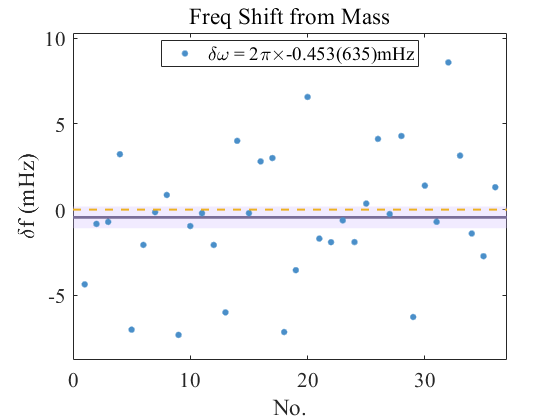


f2 = figure; hold on;

xmin = 0;
xmax = diff_n+1;
ymin = min([-abs(dfm*0.2) min(df)*0.8 min(df)*1.2]);
ymax = max([abs(dfm*0.2) max(df)*0.8 max(df)*1.2]);

n1 = [1 2 3 4];
patch_list = [0 dfm-dfs ; diff_n+1 dfm-dfs ; diff_n+1 dfm+dfs ; 0 dfm+dfs];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],'EdgeColor','none');
l1 = plot([0 xmax],[dfm dfm],Color=[0.48 0.43 0.60],LineWidth=2);

l2 = plot([1:diff_n],df,'.','MarkerSize',15);
l2.Color = [0.29,0.56,0.79];

l3 = plot([0 xmax],[0 0],'--','LineWidth',1.5,Color=[0.93 0.69 0.13]);

if diff_n < 6
    xticks([]);
end

xlim([xmin xmax]);
ylim([ymin ymax]);

xlabel('No.');
ylabel('\deltaf (mHz)');
title('Freq Shift from Mass');
legend('','',['\delta\omega = 2\pi\times',num2str(dfm,'%.3f'),'(',num2str(dfs*1e3,'%.0f'),')mHz'],'',...
    'Location','best');
grid off;
box on;

set(f2,'Visible','on');
set(gca,'FontSize',16,'FontName','Times New Roman');


if save_data == 1
    savefig(f1,[main_dir_0,'dRp.fig']);
    saveas(f1,[main_dir_0,'dRp.png']);
    savefig(f11,[main_dir_0,'dB.fig']);
    saveas(f11,[main_dir_0,'dB.png']);
    % savefig(f12,[main_dir_0,'co_dB.fig']);
    % saveas(f12,[main_dir_0,'co_dB.png']);
    savefig(f2,[main_dir_0,'df.fig']);
    saveas(f2,[main_dir_0,'df.png']);

    save([main_dir_0,'diffR.mat']);
end